% Import Dataset 
clc; clear; close all;

data = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule', 'preserve'); % preserves original headers
data.Properties.VariableNames{1} = 'SampleID';

observations_count = length(data.SampleID);

%variable traits data (y) 
traits = data.Properties.VariableNames(2:21);
numof_traits = length(traits);

%wavelengths data (x)
wavelengths = str2double(data.Properties.VariableNames(22:end));
wave_count = 1721;

% spectra + traits data
traits_data = table2array(data(:,2:21)); 
spectra_data = table2array(data(:, 22:end));

Correct import of data and separation of data into traits and spectra is done in the first section. The dataset does not have any time series, also the wavelengths from 400nm to 1800nm are captured in a interval of 1ms. 

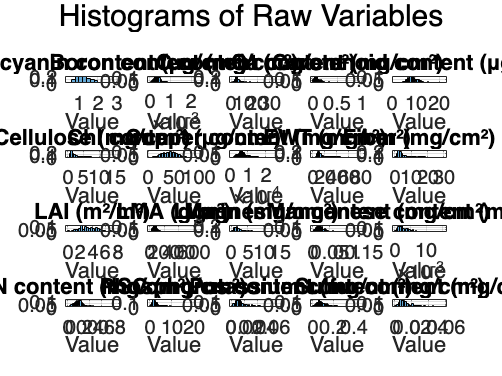

% Preliminary Visualization

nVars = size(traits_data, 2);
nCols = 5;               % Number of columns for subplot grid
nRows = ceil(nVars / nCols);

figure('Name', 'Histograms of Variables', 'NumberTitle', 'off');
for i = 1:nVars
    subplot(nRows, nCols, i);
    data_i = traits_data(:, i);
    data_i = data_i(~isnan(data_i));  % remove NaNs
    histogram(data_i, 'Normalization', 'probability');
    title(traits{i}, 'Interpreter', 'none');
    xlabel('Value');
    ylabel('Probability');
    grid on;
end
sgtitle('Histograms of Raw Variables');

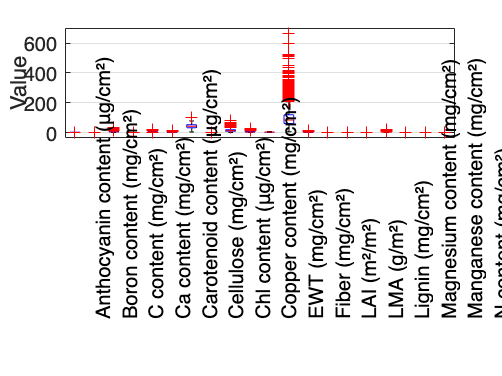


%% 2. Boxplot of variables before normalization [OPTIONAL]

figure;
boxplot(traits_data, 'Labels', traits, 'LabelOrientation', 'inline');
ylabel('Value');
grid on;

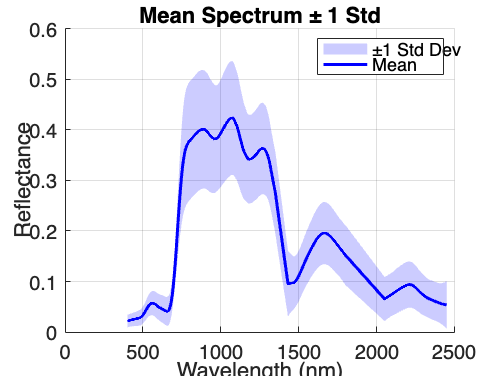


% Spectra mean and std plot

spectra_mean  = mean(spectra_data, 1, 'omitnan');
spectra_std = std(spectra_data,0,1,'omitnan');

figure; hold on; grid on;
fill([wavelengths fliplr(wavelengths)], ...
     [spectra_mean - spectra_std, fliplr(spectra_std + spectra_mean)], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
plot(wavelengths, spectra_mean, 'b', 'LineWidth', 1.5);

xlabel('Wavelength (nm)');
ylabel('Reflectance');
title('Mean Spectrum ± 1 Std');
legend('±1 Std Dev', 'Mean');

The above code snippets visualizes the traits and it's wavelength distribution, skewness across.

% Normalization + PCA calculation + Correlationmatrix

%normalize
normalized_spectra_data = (spectra_data - spectra_mean)./spectra_std;

% PCA 
[coeff, score, latent, tsquared, explained] = pca(normalized_spectra_data, 'Algorithm','svd');

 
idx = 1:wave_count

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


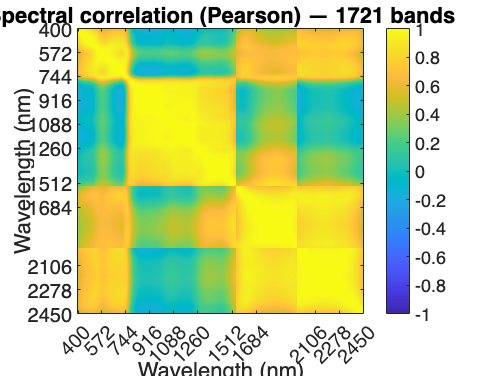

normalized_spectra_data_s = normalized_spectra_data(:,idx);
wavelengths_s = wavelengths(idx);

% correlation
R = corr(normalized_spectra_data_s, 'Type','Pearson', 'Rows','pairwise');

% plot heatmap
figure; 
clf;
imagesc(wavelengths_s, wavelengths_s, R, [-1 1]); axis image; colormap(parula); colorbar;
xlabel('Wavelength (nm)'); ylabel('Wavelength (nm)');
title(sprintf('Spectral correlation (%s) — %d bands', 'Pearson', numel(idx)));
set(gca,'XTick',wavelengths_s(1:round(numel(wavelengths_s)/10):end), ...
        'YTick',wavelengths_s(1:round(numel(wavelengths_s)/10):end));

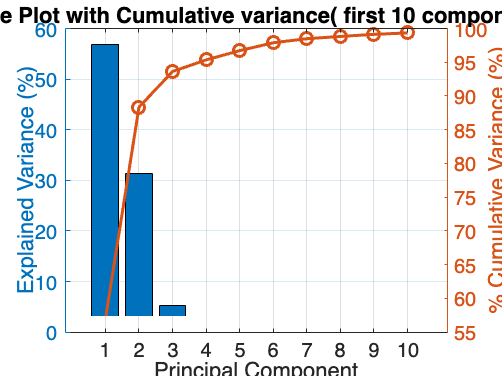

% Scree Plot ( Explained Variance) + Cumulative variance

% Scree plot
figure;
clf;

yyaxis left
bar(explained(1:10));
ylabel('Explained Variance (%)');

% Cumulative variance
yyaxis right
plot(cumsum(explained(1:10)), '-o', 'LineWidth', 1.5);
ylabel('% Cumulative Variance (%)');

xlabel('Principal Component')
title('Scree Plot with Cumulative variance( first 10 components)');
grid on;

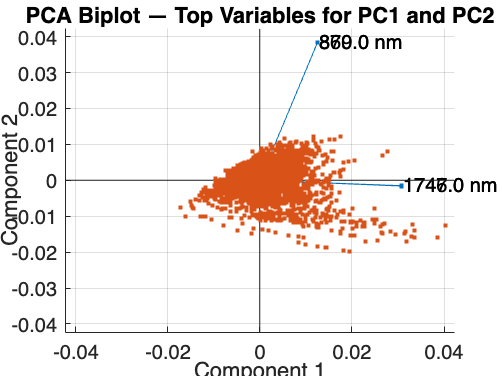

% Biplot for top unique Principal components

% Get top 2 unique variables from PC1 and PC2
[~, idx1] = maxk(abs(coeff(:,1)), 2);
[~, idx2] = maxk(abs(coeff(:,2)), 2);
theseVars = unique([idx1, idx2]);

% Labels
varLabels = arrayfun(@(x) sprintf('%.1f nm', wavelengths(x)), ...
                     theseVars, 'UniformOutput', false);

% Plot
figure;
biplot(coeff(theseVars, 1:2), ...
       'Scores', score(:,1:2), ...
       'VarLabels', varLabels);
title('PCA Biplot — Top Variables for PC1 and PC2');

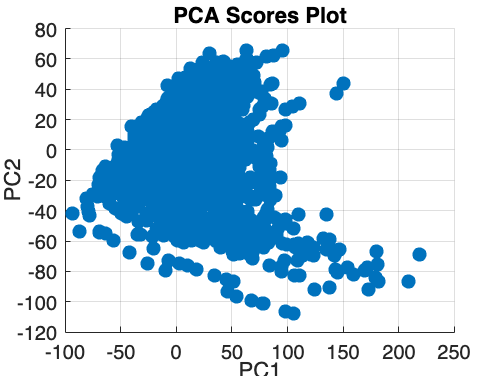



% Scores plot (PC1 vs PC2)
figure;
scatter(score(:,1), score(:,2), 50, 'filled');
xlabel('PC1');
ylabel('PC2');
title('PCA Scores Plot');
grid on;

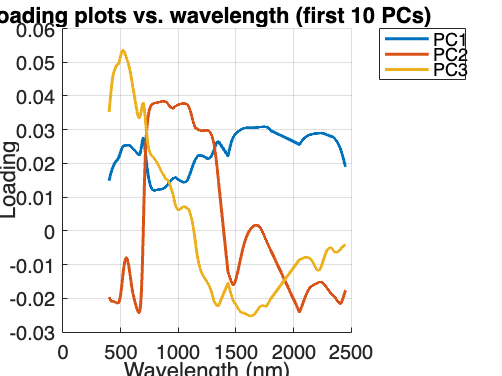

% Loading Plot

% Loading plots
figure();
clf; 
hold on;

numPC = 3;
colors = lines(numPC);

for k = 1:numPC
    plot(wavelengths, coeff(:,k), 'LineWidth', 1.5, 'Color', colors(k,:));
end

xlabel('Wavelength (nm)'); 
ylabel('Loading');
legend("PC"+string(1:numPC), 'Location','bestoutside');
title('Loading plots vs. wavelength (first 10 PCs)');
grid on;